# Derive, modify and plot the stream network

The stream network is a subset of the flow network. Often, this subset is defined as having a minimum upstream area. The idea is that if upstream area exceeds a critical value than flow becomes channelized in stream networks.

STREAMobj are the TopoToolbox class that stores stream networks. Again, STREAMobj is also the constructor function of this class. Here we simply assume that streams initiate at upstream areas greater than 1000 pixels. 

DEM = GRIDobj('srtm_bigtujunga30m_utm11.tif');
FD  = FLOWobj(DEM);
S   = STREAMobj(FD,'minarea',1000);

## Plot the stream network

The stream network can be plotted using the function plot. The function overloads the built-in function plot and can be called in nearly the same way.

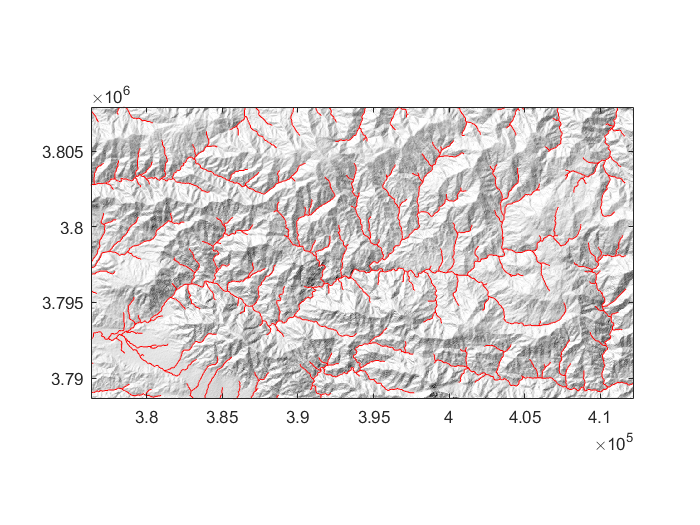

imageschs(DEM,[],'colormap',[1 1 1],'colorbar',false)
hold on
plot(S,'r')
hold off

## Modify the stream network

Frequently, we might be only interested in parts of the river network. STREAMobj has a number of methods that can modify the geometry of the network. For example, we may be interested in only the largest basin.

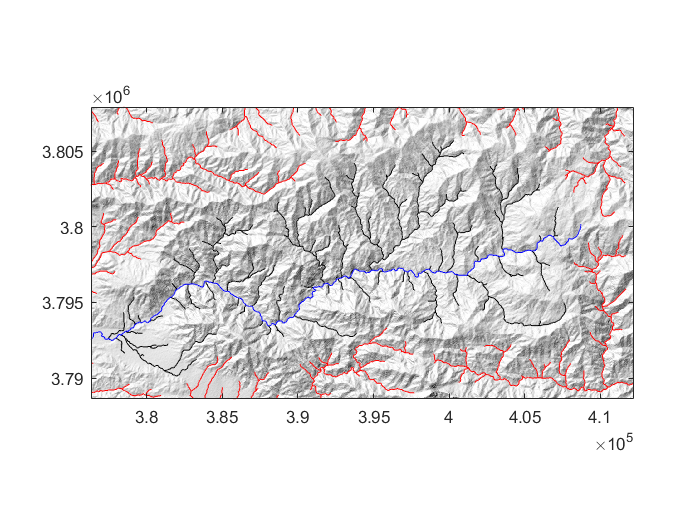

S2 = klargestconncomps(S);
St = trunk(S2);
imageschs(DEM,[],'colormap',[1 1 1],'colorbar',false)
hold on
plot(S,'r')
plot(S2,'k')
plot(St,'b')
hold off

There are many more functions to modify the stream network, e.g. `trunk`, `modify`, `removeshortstreams`, ...

## Plot the longitudinal stream profile

Applications in tectonic geomorphology are often interested in longitudinal profiles and features such as knickpoints. Visual inspection of the profile provides a first clue for these features.

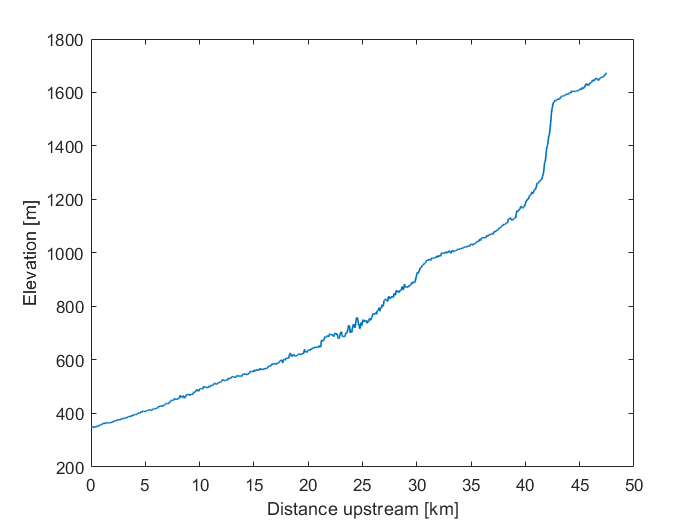

plotdz(St,DEM,'dunit','km')